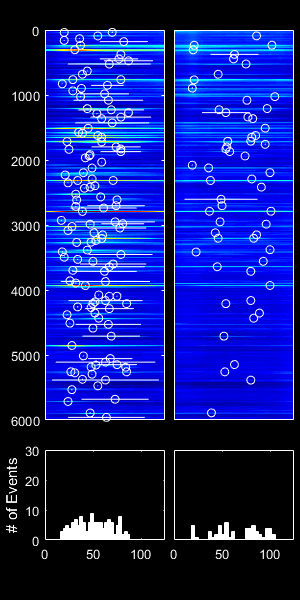

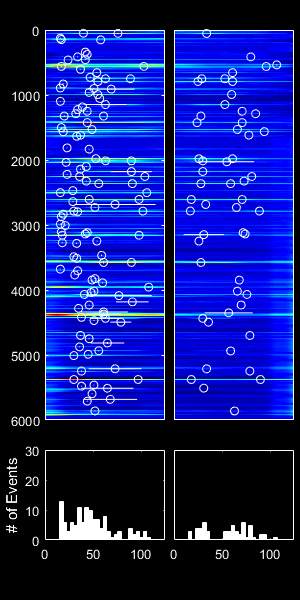

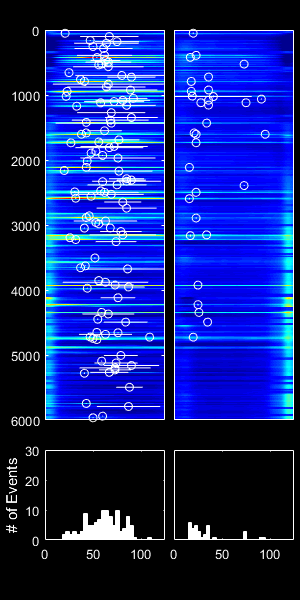

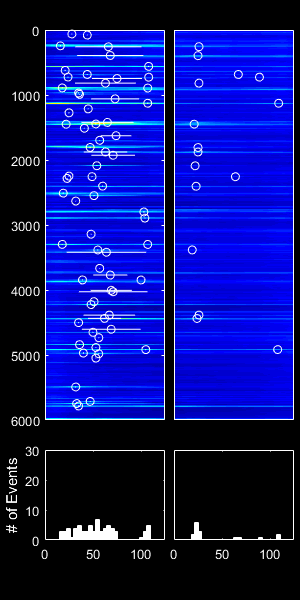

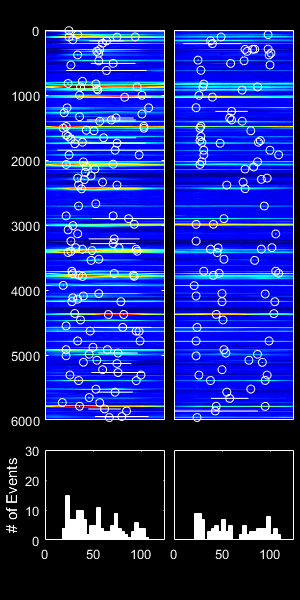

%%NBQX locations for right dominant events
paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\Intact RWM\ICmovs_peaks_dFoF_remflash.mat';
         'M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\Puncture RWM\DUP_Experiment-430_P7_Snap25GC6s_NBQX_PCA\ICmovs_peaks_dFoF_remflash.mat';
         'M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\Puncture RWM\DUP_Experiment-468_Snap25GC6s_NBQXtoRWM_PCA\ICmovs_peaks_dFoF_remflash.mat';
         'M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\Puncture RWM\DUP_Experiment-613_P7_Snap25GC6s_vGluT3het_NBQX_L_PCA\ICmovs_peaks_dFoF_remflash.mat';
         'M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\Puncture RWM\DUP_Experiment-650_Snap25GC6s_NBQX_PCA\ICmovs_peaks_dFoF_remflash.mat';
};

groupHistoR = [];
runNearNeigh = [];

for i=1:size(paths)
    load(paths{i});
    nearNeighbor = [];
    [peaksBinaryL] = getPeaks_dFoF(smLIC,0,0.02);
    [peaksBinaryR] = getPeaks_dFoF(smRIC,1,0.02);
     [peakStat, eventStats] = peakStats_dFoF(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
     
     rightTable = eventStats(contains(eventStats.leftOrRightDom,'Right'),:);
     leftTable = eventStats(contains(eventStats.leftOrRightDom,'Left'),:);
     m = size(rightTable,1);
     for j = 1:m
         nearNeighbor(j) = min(abs(leftTable.tloc-rightTable(j,:).tloc));
     end
     nearNeigh(i) = mean(nearNeighbor);
     
     rightDomEventLoc = rightTable.xloc;
     groupHistoR = [groupHistoR; abs(rightDomEventLoc(nearNeighbor>10)-125)];
     
     
     runNearNeigh = [runNearNeigh; nearNeighbor'];
     
end

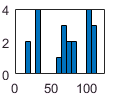


edges = 1:7:125;
edgesX = 4.5:7:120;
shift = 0;
h = figure;
h.Units = 'inches';
h.Position = [5 5 (4/4)*.8 (3/3)*1];
histogram(groupHistoR,edges,'FaceAlpha',1);
%line([edgesX+shift; edgesX+shift],[vg3_histo' + vg3_histoerr';vg3_histo' - vg3_histoerr'],'Color','r');
%line([edgesX; edgesX],[vg3bil_histo' + vg3bil_histoerr';vg3bil_histo' - vg3bil_histoerr'],'Color','k');
xlim([0 125])

%figure; histogram(groupHistoR,15);


function [groupHistoL,groupHistoR,totalEvents,individualStats, individualPks] = analGroupData(paths,plotFlag)
    groupHistoL = [];
    groupHistoR = [];
    totalEvents = [];
    individualStats = [];

    for i=1:size(paths)
         %load(paths{i},'-regexp','^(?!LICmov|RICmov)...');
         load(paths{i});
         [peaksBinaryL] = getPeaks_dFoF(smLIC,0,0.02);
         [peaksBinaryR] = getPeaks_dFoF(smRIC,1,0.02);
         savefile = '\ICmovs_peaks_dFoF.mat';
         [path, fn, ext ] = fileparts(paths{i});
         save([path savefile],'smLIC','smRIC','peaksBinaryR','peaksBinaryL');
        %size(peaksBinaryR)
        %size(peaksBinaryL)
        
        [peakStat, eventStats] = peakStats_dFoF(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
       
        %eventStat = table(eventLabel, eventClassification, leftOrRightDom, numPeaks, domAmp, maxLAmp, maxRAmp,xloc, tloc, hwt, hwx);
        peaksL = peakStat{1};
        peaksR = peakStat{2};
        groupHistoL = [groupHistoL; peaksL(:,2)];
        groupHistoR = [groupHistoR; peaksR(:,2)];
        histoLat = [peaksL(:,2); abs(peaksR(:,2)-125)];
        histoLat = histoLat(histoLat > 30);
        histoLat
        histoLat = histoLat(histoLat < 50);
        histoMed = [peaksL(:,2); abs(peaksR(:,2)-125)];
        histoMed = histoMed(histoMed > 50);
        histoMed = histoMed(histoMed < 70);
        totalEvents = [totalEvents; eventStats];
        [max(eventStats.eventLabel) median(eventStats.domAmp) median(eventStats.hwt) nanmedian(eventStats.hwx) size((find(eventStats.numPeaks > 1)),1)/max(eventStats.eventLabel)*100 size(histoLat,1) median(eventStats.integral)]
        individualStats(i,:) = [max(eventStats.eventLabel) median(eventStats.domAmp) median(eventStats.hwt) nanmedian(eventStats.hwx) size((find(eventStats.numPeaks > 1)),1)/max(eventStats.eventLabel)*100 size(histoLat,1) median(eventStats.integral) size(histoMed,1)];
        individualPks{i} = [peaksL(:,2); abs(peaksR(:,2)-125)];
        
        if(plotFlag)
          plotTimeSeries_dFoF(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
        end
    
    end
    
end